%% LINMA1510 Lab 2 Analysis

%===============================================================%
%                                                               %
%   LINMA1510: Lab2 - Analysis and treatment of the data        %
%                                                               %
%   2024-2025                                                   %
%                                 <                              %
%   Gianluca Bianchin                                           %
%   Renato Vizuete                                              %
%   François Wielant                                            %
%                                                               %
%===============================================================%
  
clear all;
clc;
close all;

%Open and run the simulink file:

sim('lab2.slx')

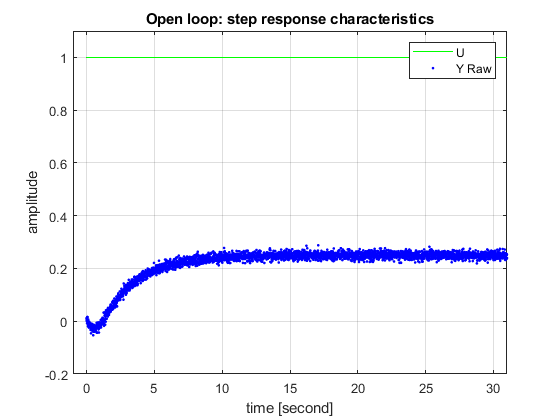



%Plot Open Loop characteristics:    
Y_Raw = plot(simout_T, simout_OL(:, 1), '.b');
hold on
U = plot(simout_T, simout_OL(:, 2), '-g');
xlabel('time [second]')
ylabel('amplitude')
title('Open loop: step response characteristics')
axis([-1 31 -0.2 1.1])
grid on

hold off

legend([U, Y_Raw],'U','Y Raw')

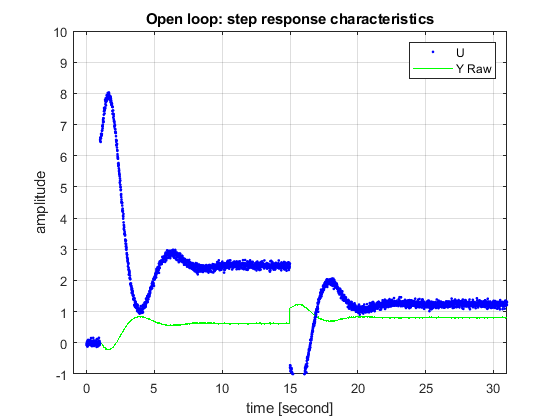

%Plot without disturbance different controller (P) 
Y_Raw = plot(simout_T, simout_CL1(:, 1), '-g');
hold on
U = plot(simout_T, simout_CL1(:, 2), '.b');

xlabel('time [second]')
ylabel('amplitude')
title('Open loop: step response characteristics')
axis([-1 31 -1 10])
grid on

hold off

legend([U, Y_Raw],'U','Y Raw')

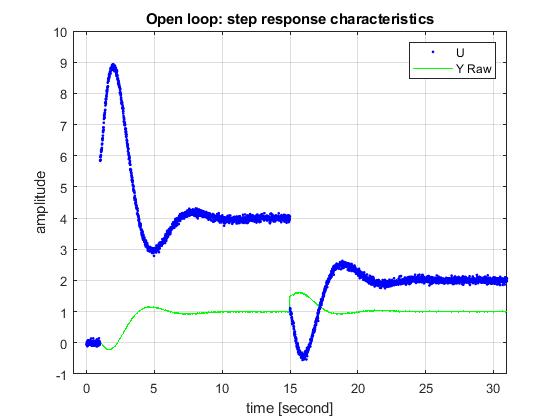


%Plot without disturbance different controller (PI) 
Y_Raw = plot(simout_T, simout_CL2(:, 1), '-g');
hold on
U = plot(simout_T, simout_CL2(:, 2), '.b');

xlabel('time [second]')
ylabel('amplitude')
title('Open loop: step response characteristics')
axis([-1 31 -1 10])
grid on

hold off

legend([U, Y_Raw],'U','Y Raw')

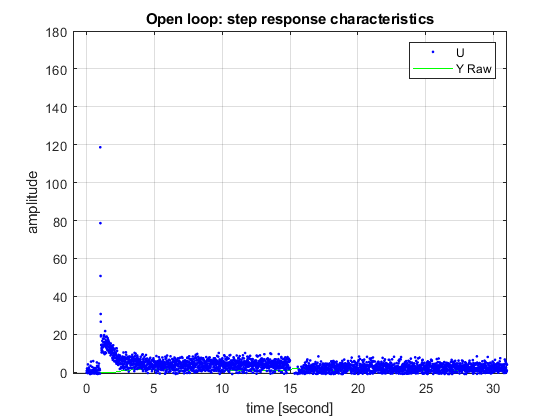


%Plot without disturbance different controller (PID) 
Y_Raw = plot(simout_T, simout_CL3(:, 1), '-g');
hold on
U = plot(simout_T, simout_CL3(:, 2), '.b');

xlabel('time [second]')
ylabel('amplitude')
title('Open loop: step response characteristics')
axis([-1 31 -1 180])
grid on

hold off

legend([U, Y_Raw],'U','Y Raw')


P_SD_sum = table(simout_T, simout_CL1(:, 1),'Variable' , {'COlonne1' , 'Colonne2'})

P_SD_sum = 5001×2 table
    COlonne1     Colonne2 
    ________    __________

         0         0.01165
      0.01       0.0062726
      0.02      0.00076514
      0.03       0.0035421
      0.04       -0.006927
      0.05        0.017009
      0.06      0.00065076
      0.07        0.018048
      0.08       0.0027404
      0.09       0.0088437
       0.1       -0.014306
      0.11      -0.0068324
      0.12        0.012653
      0.13      -0.0061831
      0.14       0.0059945
      0.15       -0.003367


P_SD2 = table(simout_T, simout_CL1(:, 2),'Variable' , {'COlonne1' , 'Colonne2'})

P_SD2 = 5001×2 table
    COlonne1     Colonne2 
    ________    __________

         0       -0.075722
      0.01       -0.040772
      0.02      -0.0049734
      0.03       -0.023023
      0.04        0.045026
      0.05        -0.11056
      0.06      -0.0042299
      0.07        -0.11731
      0.08       -0.017813
      0.09       -0.057484
       0.1        0.092989
      0.11        0.044411
      0.12       -0.082242
      0.13         0.04019
      0.14       -0.038964
      0.15        0.021886


writetable(P_SD_sum ,'Controle_P_sum_d.txt')
writetable(P_SD2 ,'Controle_P_d.txt')

PI_SD_sum = table(simout_T, simout_CL2(:, 1),'Variable' , {'COlonne1' , 'Colonne2'})

PI_SD_sum = 5001×2 table
    COlonne1     Colonne2 
    ________    __________

         0         0.01165
      0.01       0.0062722
      0.02      0.00076373
      0.03       0.0035396
      0.04      -0.0069307
      0.05        0.017005
      0.06      0.00064518
      0.07        0.018041
      0.08       0.0027313
      0.09       0.0088322
       0.1        -0.01432
      0.11      -0.0068483
      0.12        0.012636
      0.13      -0.0062007
      0.14        0.005976
      0.15      -0.0033862


PI_SD2 = table(simout_T, simout_CL2(:, 2),'Variable' , {'COlonne1' , 'Colonne2'})

PI_SD2 = 5001×2 table
    COlonne1     Colonne2 
    ________    __________

         0        -0.06815
      0.01       -0.036909
      0.02      -0.0048016
      0.03       -0.021055
      0.04         0.04013
      0.05       -0.099763
      0.06      -0.0043762
      0.07        -0.10615
      0.08       -0.016928
      0.09        -0.05267
       0.1        0.082606
      0.11        0.039163
      0.12       -0.074692
      0.13        0.035267
      0.14       -0.035852
      0.15        0.018805


writetable(PI_SD_sum ,'Controle_PI_sum_d.txt')
writetable(PI_SD2 ,'Controle_PI_d.txt')
PID_SD_sum = table(simout_T, simout_CL3(:, 1),'Variable' , {'COlonne1' , 'Colonne2'})

PID_SD_sum = 5001×2 table
    COlonne1     Colonne2 
    ________    __________

         0         0.01165
      0.01       0.0063746
      0.02       0.0010606
      0.03       0.0039909
      0.04      -0.0063654
      0.05        0.017587
      0.06       0.0013244
      0.07        0.018889
      0.08       0.0038184
      0.09        0.010184
       0.1       -0.012752
      0.11      -0.0052552
      0.12        0.014044
      0.13      -0.0048662
      0.14       0.0072739
      0.15      -0.0021334


PID_SD2 = table(simout_T, simout_CL3(:, 2),'Variable' , {'COlonne1' , 'Colonne2'})

PID_SD2 = 5001×2 table
    COlonne1    Colonne2 
    ________    _________

         0        -2.2321
      0.01       -0.37637
      0.02        0.77777
      0.03      -0.086362
      0.04         1.9241
      0.05        -3.4009
      0.06         1.0007
      0.07        -2.7553
      0.08         1.1659
      0.09       -0.51323
       0.1         4.0601
      0.11         1.0688
      0.12        -3.0404
      0.13         1.7307
      0.14        -1.2623
      0.15         1.0113


writetable(PID_SD_sum ,'Controle_PID_sum_d.txt')
writetable(PID_SD2 ,'Controle_PID_d.txt')


% Use the zoom to see the details on the figure.